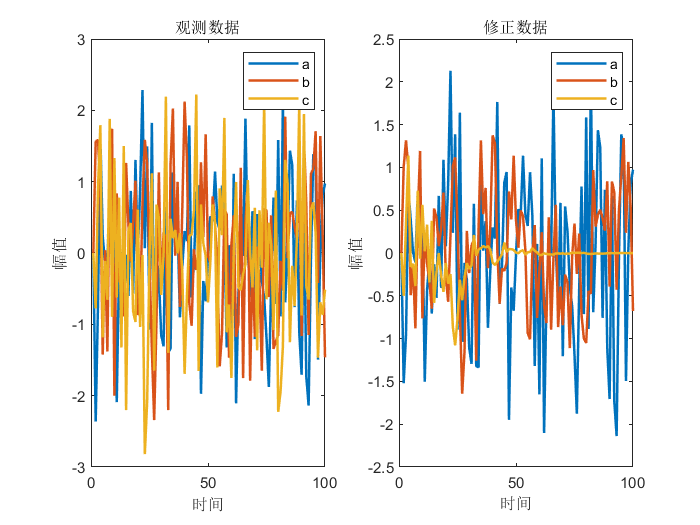

clear all;close all; clc;
sigma_n2=[0.9 1 1.1];%测量噪声方差
a=0.9;%状态矩阵
sigma_u2=1;%观测噪声方差
mu_s=0;%起始状态均值
sigma_s2=1;%起始状态方差
num=length(sigma_n2);
n=100;%仿真次数
s1=zeros(num,n);%预测状态
m1=zeros(num,n);%最小预测MSE
k=zeros(num,n);%卡尔曼增益
s2=zeros(num,n);%修正状态
m2=zeros(num,n);%修正最小MSE
x=zeros(num,n);
for j=1:num
    for i=1:n%第一个数存储下标为-1的数据
        if i==1
            s2(j,i)=mu_s;
            m2(j,i)=sigma_s2;
            x(j,i)=0;
        else
            x(j,i)=randn(1, 1,sigma_u2)+mu_s;
            s1(j,i)=a*s2(j,i-1);
            m1(j,i)=a^2*m2(j,i-1)+sigma_u2;
            k(j,i)=m1(j,i)/(sigma_n2(j)^(i-2)+m1(j,i));
            s2(j,i)=s1(j,i)+k(j,i)*(x(j,i)-s1(j,i));
            m2(j,i)=(1-k(j,i))*m1(j,i);
        end
    end
end
figure
subplot(1,2,1)
plot(1:n,x(1,:),"LineWidth",1.5);hold on;
plot(1:n,x(2,:),"LineWidth",1.5);hold on;
plot(1:n,x(3,:),"LineWidth",1.5);hold on;
xlabel("时间");ylabel("幅值");legend("a","b","c");title("观测数据");
subplot(1,2,2)
plot(1:n,s2(1,:),"LineWidth",1.5);hold on;
plot(1:n,s2(2,:),"LineWidth",1.5);hold on;
plot(1:n,s2(3,:),"LineWidth",1.5);hold on;
xlabel("时间");ylabel("幅值");legend("a","b","c");title("修正数据");

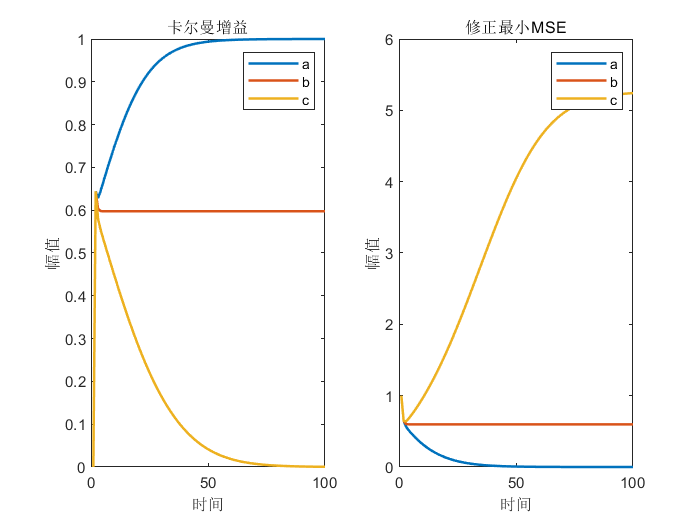

figure
subplot(121)
plot(1:n,k(1,:),"LineWidth",1.5);hold on;
plot(1:n,k(2,:),"LineWidth",1.5);hold on;
plot(1:n,k(3,:),"LineWidth",1.5);hold on;
xlabel("时间");ylabel("幅值");legend("a","b","c");title("卡尔曼增益");
subplot(122)
plot(1:n,m2(1,:),"LineWidth",1.5);hold on;
plot(1:n,m2(2,:),"LineWidth",1.5);hold on;
plot(1:n,m2(3,:),"LineWidth",1.5);hold on;
xlabel("时间");ylabel("幅值");legend("a","b","c");title("修正最小MSE");